## Derivation of Stability, Controllability

## Step 1: Rederive Dynamic Equation from Everett's MLX Script

clearvars;
sympref('MatrixWithSquareBrackets', true);
syms L_wheels L_W2CoM R theta omega_RW omega_LW dt x_CoW0 y_CoW0 psi_CoW0
setAssumptions({L_wheels, L_W2CoM, R, theta, omega_RW, omega_LW, ...
    x_CoW0, y_CoW0, psi_CoW0, dt});
left_dist = R*omega_LW*dt;
right_dist = R*omega_RW*dt;
psi = (right_dist - left_dist)/(L_wheels);
% Define transformation matrices for reference frames:
R_ICC = (L_wheels/2) * ((omega_LW+omega_RW)/...
    (omega_RW-omega_LW));
ICCx = x_CoW0 - R_ICC*sin(psi_CoW0);
ICCy = y_CoW0 + R_ICC*cos(psi_CoW0);
state_vec = [x_CoW0-ICCx; y_CoW0-ICCy; psi_CoW0];
motion_vec = simplify((RotZ(psi) * state_vec) + [ICCx; ICCy; psi]);
x_CoW = motion_vec(1,1);
y_CoW = motion_vec(2,1);
z_CoW = R;
T_0_CoW_rot = simplify([RotZ(motion_vec(3,1)), [x_CoW; y_CoW; z_CoW]; 0, 0, 0, 1]);
T_0_CoW_lin = simplify([RotZ(psi_CoW0), [x_CoW0 + R*omega_RW*cos(psi_CoW0)*dt; ...
    y_CoW0 + R*omega_LW*sin(psi_CoW0)*dt; R]; 0, 0, 0, 1]);
T_CoW_LW = [eye(3), [0; (L_wheels/2); 0]; 0, 0, 0, 1];
T_CoW_RW = [eye(3), [0; -(L_wheels/2); 0]; 0, 0, 0, 1];
x_bcm = L_W2CoM * sin(theta);
y_bcm = sym(0);
z_bcm = L_W2CoM * cos(theta);
T_CoW_CoM = [eye(3), [x_bcm; y_bcm; z_bcm]; 0, 0, 0, 1];
% Test FW Kinematics:
L_wheels_numeric =  10.0;     % 10 cm distance between wheels
L_W2CoM_numeric = 30.0;     % 30 cm distance from center of wheels to CG
R_numeric = 5.0;            % 5 cm wheel radius
dt_numeric = 1.0;           % 1 second timestep
start_state = [0; 0; 0];    % start at origin
T_0_CoW_rot_partnum = subs(T_0_CoW_rot, {L_wheels, L_W2CoM, R}, ...
    {L_wheels_numeric, L_W2CoM_numeric, R_numeric});
T_0_CoW_lin_partnum = subs(T_0_CoW_lin, {L_wheels, L_W2CoM, R}, ...
    {L_wheels_numeric, L_W2CoM_numeric, R_numeric});
T_CoW_RW_partnum = subs(T_CoW_RW, {L_wheels, L_W2CoM, R}, ...
    {L_wheels_numeric, L_W2CoM_numeric, R_numeric});
T_CoW_LW_partnum = subs(T_CoW_LW, {L_wheels, L_W2CoM, R}, ...
    {L_wheels_numeric, L_W2CoM_numeric, R_numeric});
T_CoW_CoM_partnum = subs(T_CoW_CoM, {L_wheels, L_W2CoM, R}, ...
    {L_wheels_numeric, L_W2CoM_numeric, R_numeric});
syms phi_RW phi_LW phi_dot_RW phi_dot_LW theta_dot
setAssumptions({phi_RW, phi_LW, phi_dot_RW, phi_dot_LW, theta_dot});
psi = subs(psi, {(omega_RW*dt), (omega_LW*dt)}, {phi_RW, phi_LW});
J_CoW = [(R/2)*cos(psi), (R/2)*cos(psi), 0;
        (R/2)*sin(psi), (R/2)*sin(psi), 0;
        0, 0, 0;
        0, 0, 0;
        0, 0, 0;
        R/L_wheels, -R/L_wheels, 0];
Jv_CoW = J_CoW(1:3,:);
Jw_CoW = J_CoW(4:6,:);
J_CoM = [(R/2)*cos(psi), (R/2)*cos(psi), sin(theta)*cos(psi);
        (R/2)*sin(psi), (R/2)*sin(psi), sin(theta)*sin(psi);
        0, 0, cos(theta);
        0, 0, 0;
        0, 0, 1
        R/L_wheels, -R/L_wheels, 0];
Jv_CoM = J_CoM(1:3,:);
Jw_CoM = J_CoM(4:6,:);
R_0_CoW_lin = subs(T_0_CoW_lin(1:3,1:3), ...
    {psi_CoW0}, {psi})  ;
R_0_CoW_rot = subs(T_0_CoW_rot(1:3,1:3), ...
    {psi_CoW0, omega_RW*dt, omega_LW*dt}, {0, phi_RW, phi_LW});
R_0_CoW = R_0_CoW_lin;
R_0_CoM = R_0_CoW * T_CoW_CoM(1:3,1:3); 
syms L_body m_CoW m_CoM
I_CoW = make_inertia_tensor((m_CoM/L_wheels), [], [(-L_wheels/2), (L_wheels/2)], []);
I_CoM = make_inertia_tensor((m_CoW/L_body), [], [], [(-L_W2CoM), (L_body-L_W2CoM)]);
D_CoW = m_CoW*(Jv_CoW')*Jv_CoW + (Jw_CoW')*R_0_CoW*I_CoW*(R_0_CoW')*Jw_CoW;
D_CoM = m_CoM*(Jv_CoM')*Jv_CoM + (Jw_CoM')*R_0_CoM*I_CoM*(R_0_CoM')*Jw_CoM;
D_matrix = simplify(D_CoW + D_CoM);
q_vector = [phi_dot_RW; phi_dot_LW; theta_dot];
KE_tot = simplify((1/2)*(q_vector')*D_matrix*q_vector);
syms g
PE_tot = m_CoM*g*(R+L_W2CoM*cos(theta));
Lagn = simplify(KE_tot - PE_tot);
% Create handles for existing sym variables as functions of time so that
% the time derivative can be taken more easily:
syms phi_ddot_RW phi_ddot_LW theta_ddot
f_phiRW = makeFunctionOfTime('phi_RW');
f_phiRW_dot = makeFunctionOfTime('phi_dot_RW');
f_phiLW = makeFunctionOfTime('phi_LW');
f_phiLW_dot = makeFunctionOfTime('phi_dot_LW');
f_theta = makeFunctionOfTime('theta');
f_theta_dot = makeFunctionOfTime('theta_dot');
setAssumptions({f_phiRW, f_phiRW_dot, f_phiLW, f_phiLW_dot, f_theta, f_theta_dot});

% Torque associated with phi_RW:
Tau_phiRW = computeTau(Lagn, phi_RW, phi_dot_RW, sym('t'), ...
    {phi_RW, phi_LW, theta}, ...                    % qcells
    {phi_dot_RW, phi_dot_LW, theta_dot}, ...        % qdotcells
    {phi_ddot_RW, phi_ddot_LW, theta_ddot}, ...     % qddotcells
    {f_phiRW, f_phiLW, f_theta}, ...                % fqcells
    {f_phiRW_dot, f_phiLW_dot, f_theta_dot});        % fqdotcells

% Torque associated with phi_LW:
Tau_phiLW = computeTau(Lagn, phi_LW, phi_dot_LW, sym('t'), ...
    {phi_RW, phi_LW, theta}, ...                    % qcells
    {phi_dot_RW, phi_dot_LW, theta_dot}, ...        % qdotcells
    {phi_ddot_RW, phi_ddot_LW, theta_ddot}, ...     % qddotcells
    {f_phiRW, f_phiLW, f_theta}, ...                % fqcells
    {f_phiRW_dot, f_phiLW_dot, f_theta_dot});        % fqdotcells

% Torque associated with theta:
Tau_theta = computeTau(Lagn, theta, theta_dot, sym('t'), ...
    {phi_RW, phi_LW, theta}, ...                    % qcells
    {phi_dot_RW, phi_dot_LW, theta_dot}, ...        % qdotcells
    {phi_ddot_RW, phi_ddot_LW, theta_ddot}, ...     % qddotcells
    {f_phiRW, f_phiLW, f_theta}, ...                % fqcells
    {f_phiRW_dot, f_phiLW_dot, f_theta_dot}) ;       % fqdotcells


$$\frac{\mathrm{d}}{\mathrm{d}t}\left(\left\lbrack \begin{array}{c}
\phi_{\mathrm{RW}} \\
\phi_{\mathrm{LW}} \\
\theta \\
{\dot{\phi} }_{\mathrm{RW}} \\
{\dot{\phi} }_{\mathrm{LW}} \\
\dot{\theta} 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
{\dot{\phi} }_{\mathrm{RW}} \\
{\dot{\phi} }_{\mathrm{LW}} \\
\dot{\theta} \\
\mathit{\mathbf{E}}\left\lbrack \begin{array}{c}
\tau_{\mathrm{RW}} \\
\tau_{\mathrm{LW}} \\
m_{\mathrm{CoM}} {gL}_{\mathrm{W2CoM}} \sin \left(\theta \right)
\end{array}\right\rbrack -\mathit{\mathbf{F}}\left\lbrack \begin{array}{c}
{\dot{\phi} }_{\mathrm{RW}} \\
{\dot{\phi} }_{\mathrm{LW}} \\
\dot{\theta} 
\end{array}\right\rbrack -\mathit{\mathbf{H}}
\end{array}\right\rbrack$$


[M_matrix, C_matrix, V_matrix, G_matrix] = make_dynamics_expr(...
        [Tau_phiRW; Tau_phiLW; Tau_theta], ...
        [phi_ddot_RW; phi_ddot_LW; theta_ddot], ...
        [phi_dot_RW; phi_dot_LW; theta_dot])

$$M\_matrix = \left[\begin{array}{ccc} \frac{R^{2}\,\left(4\,m_{\mathrm{CoM}}+3\,m_{\mathrm{CoW}}\right)}{12} & \frac{R^{2}\,\left(2\,m_{\mathrm{CoM}}+3\,m_{\mathrm{CoW}}\right)}{12} & \frac{R\,m_{\mathrm{CoM}}\,\sin\left(\theta \right)}{2}\\ \frac{R^{2}\,\left(2\,m_{\mathrm{CoM}}+3\,m_{\mathrm{CoW}}\right)}{12} & \frac{R^{2}\,\left(4\,m_{\mathrm{CoM}}+3\,m_{\mathrm{CoW}}\right)}{12} & \frac{R\,m_{\mathrm{CoM}}\,\sin\left(\theta \right)}{2}\\ \frac{R\,m_{\mathrm{CoM}}\,\sin\left(\theta \right)}{2} & \frac{R\,m_{\mathrm{CoM}}\,\sin\left(\theta \right)}{2} & m_{\mathrm{CoW}}\,{L_{\mathrm{W2CoM}}}^{2}-m_{\mathrm{CoW}}\,L_{\mathrm{W2CoM}}\,L_{\mathrm{body}}+\frac{m_{\mathrm{CoW}}\,{L_{\mathrm{body}}}^{2}}{3}+m_{\mathrm{CoM}} \end{array}\right]$$

$$C\_matrix = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ -\frac{R\,m_{\mathrm{CoM}}\,\dot{\theta }\,\cos\left(\theta \right)}{2} & -\frac{R\,m_{\mathrm{CoM}}\,\dot{\theta }\,\cos\left(\theta \right)}{2} & 0 \end{array}\right]$$

$$V\_matrix = \left[\begin{array}{c} 0\\ 0\\ -\frac{R\,m_{\mathrm{CoM}}\,\dot{\theta }\,\cos\left(\theta \right)\,\left({\dot{\varphi }}_{\mathrm{LW}}+{\dot{\varphi }}_{\mathrm{RW}}\right)}{2} \end{array}\right]$$

$$G\_matrix = \left[\begin{array}{c} 0\\ 0\\ -L_{\mathrm{W2CoM}}\,g\,m_{\mathrm{CoM}}\,\sin\left(\theta \right) \end{array}\right]$$


syms tau_RW tau_LW tau_body
syms L_body m_CoW m_CoM
syms phi_RW phi_LW phi_dot_RW phi_dot_LW theta_dot
syms L_wheels L_W2CoM R theta omega_RW omega_LW dt x_CoW0 y_CoW0 psi_CoW0
E_matrix = simplify(inv(M_matrix));
% Will use MATLAB's built in "\" operator instead multiplying by inv(M_matrix)
F_matrix = simplify(M_matrix\C_matrix);
H_matrix = simplify(M_matrix\G_matrix);

syms x_1 x_2 x_3 x_4 x_5 x_6 x_3e u_1 u_2 k_11 k_12 k_13 k_14 k_15 k_16 k_21 k_22 k_23 k_24 k_25 k_26
q_dot_vec = [phi_dot_RW; phi_dot_LW; theta_dot];
q_ddot_vec = (E_matrix*[tau_RW; tau_LW; tau_body]) ...
    - (F_matrix*q_dot_vec) - H_matrix;
X_dot = simplify([q_dot_vec; q_ddot_vec]);
X_dot = simplify(subs(X_dot, {phi_RW, phi_LW, theta, phi_dot_RW, phi_dot_LW, theta_dot, tau_body,tau_RW,tau_LW}, {x_1, x_2, x_3, x_4, x_5, x_6, (m_CoM*g*L_W2CoM*sin(x_4)),u_1,u_2}));

## Step 2: Linearize Model around the System Origin (theta = 0)

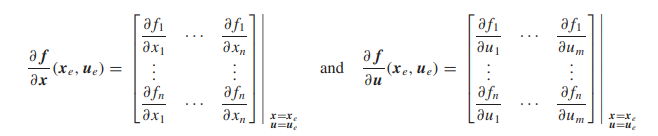

x11 = diff(X_dot(1),x_1);
x12 = diff(X_dot(1),x_2);
x13 = diff(X_dot(1),x_3);
x14 = diff(X_dot(1),x_4);
x15 = diff(X_dot(1),x_5);
x16 = diff(X_dot(1),x_6);
x21 = diff(X_dot(2),x_1);
x22 = diff(X_dot(2),x_2);
x23 = diff(X_dot(2),x_3);
x24 = diff(X_dot(2),x_4);
x25 = diff(X_dot(2),x_5);
x26 = diff(X_dot(2),x_6);
x31 = diff(X_dot(3),x_1);
x32 = diff(X_dot(3),x_2);
x33 = diff(X_dot(3),x_3);
x34 = diff(X_dot(3),x_4);
x35 = diff(X_dot(3),x_5);
x36 = diff(X_dot(3),x_6);
x41 = diff(X_dot(4),x_1);
x42 = diff(X_dot(4),x_2);
x43 = diff(X_dot(4),x_3);
x44 = diff(X_dot(4),x_4);
x45 = diff(X_dot(4),x_5);
x46 = diff(X_dot(4),x_6);
x51 = diff(X_dot(5),x_1);
x52 = diff(X_dot(5),x_2);
x53 = diff(X_dot(5),x_3);
x54 = diff(X_dot(5),x_4);
x55 = diff(X_dot(5),x_5);
x56 = diff(X_dot(5),x_6);
x61 = diff(X_dot(6),x_1);
x62 = diff(X_dot(6),x_2);
x63 = diff(X_dot(6),x_3);
x64 = diff(X_dot(6),x_4);
x65 = diff(X_dot(6),x_5);
x66 = diff(X_dot(6),x_6);

u11 = diff(X_dot(1),u_1);
u12 = diff(X_dot(1),u_2);
u21 = diff(X_dot(2),u_1);
u22 = diff(X_dot(2),u_2);
u31 = diff(X_dot(3),u_1);
u32 = diff(X_dot(3),u_2);
u41 = diff(X_dot(4),u_1);
u42 = diff(X_dot(4),u_2);
u51 = diff(X_dot(5),u_1);
u52 = diff(X_dot(5),u_2);
u61 = diff(X_dot(6),u_1);
u62 = diff(X_dot(6),u_2);

%Robot parameters are asumed to be 1

 A = [x11 x12 x13 x14 x15 x16;x21 x22 x23 x24 x25 x26;x31 x32 x33 x34 x35 x36;x41 x42 x43 x44 x45 x46;x51 x52 x53 x54 x55 x56;x61 x62 x63 x64 x65 x66;]

A = subs(A,{x_1,x_2,x_3,x_4,x_5,x_6,u_1,u_2},{0,0,0,0,0,0,0,0});
A = subs(A,{L_body,m_CoW, m_CoM,phi_RW, phi_LW ,phi_dot_RW ,phi_dot_LW ,theta_dot,L_wheels ,L_W2CoM ,R ,theta ,omega_RW ,omega_LW ,dt ,x_CoW0 ,y_CoW0,psi_CoW0,g},{1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,-9.8})

$$A = \left[\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{147}{20} & -\frac{147}{20} & 0 & 0 \end{array}\right]$$


B = [u11 u12;u21 u22;u31 u32;u41 u42;u51 u52;u61 u62;]

B = subs(B,{x_1,x_2,x_3,x_4,x_5,x_6,u_1,u_2},{0,0,0,0,0,0,0,0});
B = subs(B,{L_body,m_CoW, m_CoM,phi_RW, phi_LW ,phi_dot_RW ,phi_dot_LW ,theta_dot,L_wheels ,L_W2CoM ,R ,theta ,omega_RW ,omega_LW ,dt ,x_CoW0 ,y_CoW0,psi_CoW0,g},{1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,-9.8})

$$B = \left[\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{7}{2} & -\frac{5}{2}\\ -\frac{5}{2} & \frac{7}{2}\\ 0 & 0 \end{array}\right]$$



A = double(A)

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0   -7.3500   -7.3500         0         0


B = double(B)

B =          0         0
         0         0
         0         0
    3.5000   -2.5000
   -2.5000    3.5000
         0         0


## Step 3: Determine if System is Stable at Origin

syms s
eigA = A-s*eye(6);
detA = det(eigA) == 0

$$detA = \frac{s^{2}\,\left(20\,s^{4}+147\,s^{2}\right)}{20}=0$$


S = solve(detA)

$$S = \left[\begin{array}{c} 0\\ 0\\ 0\\ 0\\ -\frac{7\,\sqrt{15}\,\mathrm{i}}{10}\\ \frac{7\,\sqrt{15}\,\mathrm{i}}{10} \end{array}\right]$$


if isreal(S)
    if real(S) < 0
        disp('Stable')
    else
        disp('Unstable')
    end
else
    disp('Syetem is unstable');
end

Syetem is unstable


The system has no real roots. This means that the system is not stable

## Step 4: Determine Controllability

matrix1 = [B A*B A^2*B A^3*B A^4*B A^5*B];
matrix2 = [B A*B A^2*B A^3*B A^4*B A^5*B A^6];


if rank(matrix2) == rank(matrix1)
    disp('System is controllable')
else
    disp('System is uncontrollable')
end

System is controllable


## Local Function Declarations

### Rigid Body Motion Transformations

function R = RotZ(alpha)
R = [cos(alpha), -sin(alpha), 0; 
    sin(alpha), cos(alpha), 0;
    0, 0, 1];
end

function R = RotY(beta)
R = [cos(beta), 0, sin(beta);
    0, 1, 0;
    -sin(beta), 0, cos(beta)];
end

function R = RotX(gamma)
R = [1, 0, 0; 
    0, cos(gamma), -sin(gamma);
    0, sin(gamma), cos(gamma)];
end

### setAssumptions()

function setAssumptions(cellarray)
for e=1:numel(cellarray)
    assume(cellarray{e}, 'real');
    assume(cellarray{e}, 'rational');
end
end

### make_teeterbot()

function tbot_struct = make_teeterbot(T_symcells, init_state, thetacom, omegarw, omegalw, tstep)
% Serves as the "constructor" for the teeterbot structure with the
% following inputs:
%   T_symcells  = cell array of all symbolic T matrices
%   init_state  = array of numerical values for x_0, y_0, z_0, and psi_0
%   thetacom    = numerical value to use for theta in symbolic T matrices
%   omegarw     = numerical value to use for omega_RW in symbolic T matrices
%   omegalw     = numerical value to use for omega_LW in symbolic T matrices
%   tstep       = numerical value to use for dt in symbolic T matrices
x_0 = init_state(1);
y_0 = init_state(2);
psi_0 = init_state(3);
if omegarw == omegalw
    % Use the "linear" transformation matrix
    tbot_struct.CoW = double(subs(T_symcells{2}, ...
        {sym('x_CoW0'), sym('y_CoW0'), sym('psi_CoW0'), ...
        sym('theta'), sym('omega_RW'), sym('omega_LW'), sym('dt')}, ...
        {x_0, y_0, psi_0, ...
        thetacom, omegarw, omegalw, tstep}));
else
    % Use the "rotational" transformation matrix
    tbot_struct.CoW = double(subs(T_symcells{1}, ...
        {sym('x_CoW0'), sym('y_CoW0'), sym('psi_CoW0'), ...
        sym('theta'), sym('omega_RW'), sym('omega_LW'), sym('dt')}, ...
        {x_0, y_0, psi_0, ...
        thetacom, omegarw, omegalw, tstep}));
end
tbot_struct.RW = tbot_struct.CoW * ...  % The CoW is the "base" for other frames
    double(subs(T_symcells{3}, ...
    {sym('x_CoW0'), sym('y_CoW0'), sym('psi_CoW0'), ...
    sym('theta'), sym('phi_RW'), sym('phi_LW'), sym('dt')}, ...
    {x_0, y_0, psi_0, ...
    thetacom, omegarw, omegalw, tstep}));
tbot_struct.LW = tbot_struct.CoW * ...  % The CoW is the "base" for other frames
    double(subs(T_symcells{4}, ...
    {sym('x_CoW0'), sym('y_CoW0'), sym('psi_CoW0'), ...
    sym('theta'), sym('phi_RW'), sym('phi_LW'), sym('dt')}, ...
    {x_0, y_0, psi_0, ...
    thetacom, omegarw, omegalw, tstep}));
tbot_struct.CoM = tbot_struct.CoW * ...  % The CoW is the "base" for other frames
    double(subs(T_symcells{5}, ...
    {sym('x_CoW0'), sym('y_CoW0'), sym('psi_CoW0'), ...
    sym('theta'), sym('phi_RW'), sym('phi_LW'), sym('dt')}, ...
    {x_0, y_0, psi_0, ...
    thetacom, omegarw, omegalw, tstep}));
end

### plot_teeterbot()

function tbot = plot_teeterbot(Tmat_s, color, linespec, width)
% Plots the teeterbot using the structure "Tmat_s" created using the
% make_teeterbot constructor function:
if ~exist('linespec', 'var')
    linespec = '-o';
end
if ~exist('color', 'var')
    color = 'k';
end
if ~exist('width', 'var')
    width = 2;
end
hold on;
% Plot "center of wheels to right wheel" link:
tbot.CoW_2_RW = plot3([Tmat_s.CoW(1,4), Tmat_s.RW(1,4)], ...
    [Tmat_s.CoW(2,4), Tmat_s.RW(2,4)], ...
    [Tmat_s.CoW(3,4), Tmat_s.RW(3,4)], ...
    linespec, 'Color', color, 'LineWidth', width);
% Plot "center of wheels to left wheel" link:
tbot.CoW_2_LW = plot3([Tmat_s.CoW(1,4), Tmat_s.LW(1,4)], ...
    [Tmat_s.CoW(2,4), Tmat_s.LW(2,4)], ...
    [Tmat_s.CoW(3,4), Tmat_s.LW(3,4)], ...
    linespec, 'Color', color, 'LineWidth', width);
% Plot "center of wheels to center of mass" link:
tbot.CoW_2_CoM = plot3([Tmat_s.CoW(1,4), Tmat_s.CoM(1,4)], ...
    [Tmat_s.CoW(2,4), Tmat_s.CoM(2,4)], ...
    [Tmat_s.CoW(3,4), Tmat_s.CoM(3,4)], ...
    linespec, 'Color', color, 'LineWidth', width);
end

### plot_frame_axes()

function Taxes = plot_frame_axes(Tmat_s, axeslen, color, linespec, width)
% Plots the teeterbot frame axes using the structure "Tmat_s" created using
% the make_teeterbot constructor function:
if ~exist('linespec', 'var')
    linespec = '--';
end
if ~exist('color', 'var')
    color = 'r';
end
if ~exist('width', 'var')
    width = 1;
end
hold on;
% Plot "center of wheels" frame axes:
Taxes.CoW_x = plot3([Tmat_s.CoW(1,4), Tmat_s.CoW(1,4) + Tmat_s.CoW(1,1)*axeslen], ...
    [Tmat_s.CoW(2,4), Tmat_s.CoW(2,4) + Tmat_s.CoW(2,1)*axeslen], ...
    [Tmat_s.CoW(3,4), Tmat_s.CoW(3,4) + Tmat_s.CoW(3,1)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.CoW_y = plot3([Tmat_s.CoW(1,4), Tmat_s.CoW(1,4) + Tmat_s.CoW(1,2)*axeslen], ...
    [Tmat_s.CoW(2,4), Tmat_s.CoW(2,4) + Tmat_s.CoW(2,2)*axeslen], ...
    [Tmat_s.CoW(3,4), Tmat_s.CoW(3,4) + Tmat_s.CoW(3,2)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.CoW_z = plot3([Tmat_s.CoW(1,4), Tmat_s.CoW(1,4) + Tmat_s.CoW(1,3)*axeslen], ...
    [Tmat_s.CoW(2,4), Tmat_s.CoW(2,4) + Tmat_s.CoW(2,3)*axeslen], ...
    [Tmat_s.CoW(3,4), Tmat_s.CoW(3,4) + Tmat_s.CoW(3,3)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
% Plot "right wheel" frame axes:
Taxes.RW_x = plot3([Tmat_s.RW(1,4), Tmat_s.RW(1,4) + Tmat_s.RW(1,1)*axeslen], ...
    [Tmat_s.RW(2,4), Tmat_s.RW(2,4) + Tmat_s.RW(2,1)*axeslen], ...
    [Tmat_s.RW(3,4), Tmat_s.RW(3,4) + Tmat_s.RW(3,1)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.RW_y = plot3([Tmat_s.RW(1,4), Tmat_s.RW(1,4) + Tmat_s.RW(1,2)*axeslen], ...
    [Tmat_s.RW(2,4), Tmat_s.RW(2,4) + Tmat_s.RW(2,2)*axeslen], ...
    [Tmat_s.RW(3,4), Tmat_s.RW(3,4) + Tmat_s.RW(3,2)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.RW_z = plot3([Tmat_s.RW(1,4), Tmat_s.RW(1,4) + Tmat_s.RW(1,3)*axeslen], ...
    [Tmat_s.RW(2,4), Tmat_s.RW(2,4) + Tmat_s.RW(2,3)*axeslen], ...
    [Tmat_s.RW(3,4), Tmat_s.RW(3,4) + Tmat_s.RW(3,3)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
% Plot "left wheel" frame axes:
Taxes.LW_x = plot3([Tmat_s.LW(1,4), Tmat_s.LW(1,4) + Tmat_s.LW(1,1)*axeslen], ...
    [Tmat_s.LW(2,4), Tmat_s.LW(2,4) + Tmat_s.LW(2,1)*axeslen], ...
    [Tmat_s.LW(3,4), Tmat_s.LW(3,4) + Tmat_s.LW(3,1)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.LW_y = plot3([Tmat_s.LW(1,4), Tmat_s.LW(1,4) + Tmat_s.LW(1,2)*axeslen], ...
    [Tmat_s.LW(2,4), Tmat_s.LW(2,4) + Tmat_s.LW(2,2)*axeslen], ...
    [Tmat_s.LW(3,4), Tmat_s.LW(3,4) + Tmat_s.LW(3,2)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.LW_z = plot3([Tmat_s.LW(1,4), Tmat_s.LW(1,4) + Tmat_s.LW(1,3)*axeslen], ...
    [Tmat_s.LW(2,4), Tmat_s.LW(2,4) + Tmat_s.LW(2,3)*axeslen], ...
    [Tmat_s.LW(3,4), Tmat_s.LW(3,4) + Tmat_s.LW(3,3)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
% Plot "center of mass" frame axes:
Taxes.CoM_x = plot3([Tmat_s.CoM(1,4), Tmat_s.CoM(1,4) + Tmat_s.CoM(1,1)*axeslen], ...
    [Tmat_s.CoM(2,4), Tmat_s.CoM(2,4) + Tmat_s.CoM(2,1)*axeslen], ...
    [Tmat_s.CoM(3,4), Tmat_s.CoM(3,4) + Tmat_s.CoM(3,1)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.CoM_y = plot3([Tmat_s.CoM(1,4), Tmat_s.CoM(1,4) + Tmat_s.CoM(1,2)*axeslen], ...
    [Tmat_s.CoM(2,4), Tmat_s.CoM(2,4) + Tmat_s.CoM(2,2)*axeslen], ...
    [Tmat_s.CoM(3,4), Tmat_s.CoM(3,4) + Tmat_s.CoM(3,2)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
Taxes.CoM_z = plot3([Tmat_s.CoM(1,4), Tmat_s.CoM(1,4) + Tmat_s.CoM(1,3)*axeslen], ...
    [Tmat_s.CoM(2,4), Tmat_s.CoM(2,4) + Tmat_s.CoM(2,3)*axeslen], ...
    [Tmat_s.CoM(3,4), Tmat_s.CoM(3,4) + Tmat_s.CoM(3,3)*axeslen], ...
    linespec, 'Color', color, 'LineWidth', width);
end

### make_inertia_tensor()

function I = make_inertia_tensor(density, xbounds, ybounds, zbounds)
syms x_temp y_temp z_temp
% Define terms to integrate:
I_xx = (y_temp^2 + z_temp^2) * density;
I_yy = (x_temp^2 + z_temp^2)*density; 
I_zz = (x_temp^2 + y_temp^2)*density;
I_xy_yx = x_temp * y_temp * density;
I_xz_zx = x_temp * z_temp * density;
I_yz_zy = y_temp * z_temp * density;
% Integrate terms across x bounds if body exists on span of x:
if ~isempty(xbounds)
    I_xx = int(I_xx, x_temp, xbounds(1), xbounds(2));
    I_yy = int(I_yy, x_temp, xbounds(1), xbounds(2));
    I_zz = int(I_zz, x_temp, xbounds(1), xbounds(2));
    I_xy_yx = int(I_xy_yx, x_temp, xbounds(1), xbounds(2));
    I_xz_zx = int(I_xz_zx, x_temp, xbounds(1), xbounds(2));
    I_yz_zy = int(I_yz_zy, x_temp, xbounds(1), xbounds(2));
else
    I_xx = subs(I_xx, {x_temp}, {0});
    I_yy = subs(I_yy, {x_temp}, {0});
    I_zz = subs(I_zz, {x_temp}, {0});
    I_xy_yx = subs(I_xy_yx, {x_temp}, {0});
    I_xz_zx = subs(I_xz_zx, {x_temp}, {0});
    I_yz_zy = subs(I_yz_zy, {x_temp}, {0});
end
% Integrate terms across y bounds if body exists on span of y:
if ~isempty(ybounds)
    I_xx = int(I_xx, y_temp, ybounds(1), ybounds(2));
    I_yy = int(I_yy, y_temp, ybounds(1), ybounds(2));
    I_zz = int(I_zz, y_temp, ybounds(1), ybounds(2));
    I_xy_yx = int(I_xy_yx, y_temp, ybounds(1), ybounds(2));
    I_xz_zx = int(I_xz_zx, y_temp, ybounds(1), ybounds(2));
    I_yz_zy = int(I_yz_zy, y_temp, ybounds(1), ybounds(2));
else
    I_xx = subs(I_xx, {y_temp}, {0});
    I_yy = subs(I_yy, {y_temp}, {0});
    I_zz = subs(I_zz, {y_temp}, {0});
    I_xy_yx = subs(I_xy_yx, {y_temp}, {0});
    I_xz_zx = subs(I_xz_zx, {y_temp}, {0});
    I_yz_zy = subs(I_yz_zy, {y_temp}, {0});
end
% Integrate terms across z bounds if body exists on span of z:
if ~isempty(zbounds)
    I_xx = int(I_xx, z_temp, zbounds(1), zbounds(2));
    I_yy = int(I_yy, z_temp, zbounds(1), zbounds(2));
    I_zz = int(I_zz, z_temp, zbounds(1), zbounds(2));
    I_xy_yx = int(I_xy_yx, z_temp, zbounds(1), zbounds(2));
    I_xz_zx = int(I_xz_zx, z_temp, zbounds(1), zbounds(2));
    I_yz_zy = int(I_yz_zy, z_temp, zbounds(1), zbounds(2));
else
    I_xx = subs(I_xx, {z_temp}, {0});
    I_yy = subs(I_yy, {z_temp}, {0});
    I_zz = subs(I_zz, {z_temp}, {0});
    I_xy_yx = subs(I_xy_yx, {z_temp}, {0});
    I_xz_zx = subs(I_xz_zx, {z_temp}, {0});
    I_yz_zy = subs(I_yz_zy, {z_temp}, {0});
end
% Formulate inertia tensor from elements:
I = [ simplify(I_xx), -simplify(I_xy_yx), -simplify(I_xz_zx);
    -simplify(I_xy_yx), simplify(I_yy), -simplify(I_yz_zy);
    -simplify(I_xz_zx), -simplify(I_yz_zy), simplify(I_zz)];
end

### makeFunctionOfTime()

function outsym = makeFunctionOfTime(symstr)
outsym = str2sym([symstr '(t)']);
end

### computeTau()

function Tau = computeTau(LagExp, qterm, qdotterm, tterm, ...
                            qcells, qdotcells, qddotcells, fqcells, fqdotcells)
% Term 1 is d/dt(dL/dqdot):
term1 = diff(LagExp, qdotterm);
term1 = subs(term1, qcells, fqcells);
term1 = subs(term1, qdotcells, fqdotcells);
term1 = diff(term1, tterm);
term1 = subs(term1, fqcells, qcells);
term1 = subs(term1, diff(fqcells,tterm), qdotcells);
term1 = subs(term1, diff(fqdotcells,tterm), qddotcells);
% Term 2 is dL/dq:
term2 = diff(LagExp, qterm);

Tau = simplify(term1 - term2);
end

### make_dynamics_expr()

function [M, C, V, G] = make_dynamics_expr(taus, tdds, tds)
M = sym(zeros(numel(taus), numel(tdds)));
C = sym(zeros(numel(taus), numel(tds)));
V = sym(zeros(numel(tds),1));
G = sym(zeros(numel(tds),1));
for e=1:numel(taus)
    % Fill in M matrix
    for e2=1:numel(tdds)
        [coef_tau, term_tau] = coeffs(taus(e), tdds(e2));
        coef_idx = find(has(term_tau, tdds(e2)));
        if ~isempty(coef_idx)
            M(e,e2) = simplify(coef_tau(coef_idx));
        end
    end
    % Fill in C matrix
    C_temp_tau = taus(e);   % Due to complexity of C matrix, terms added to C-rows will be subtracted from Tau(e) 
    for e2=1:numel(tds)
        [coef_tau, term_tau] = coeffs(C_temp_tau, tds(e2));
        coef_idx = find(has(term_tau, tds(e2)));
        if ~isempty(coef_idx)
            for e3=1:numel(coef_idx)
                linear_check = strcmp(char(tds(e2)), char(term_tau(coef_idx(e3))));
                if ~(linear_check)
                    extra_exp = regexp(char(term_tau(coef_idx(e3))), '\^(\d)', 'tokens');
                    extra_exp = str2double(cell2mat(cellfun(@cell2mat, extra_exp, ...
                        'UniformOutput', false))) - 1; % extract # from cell within cell
                    coef_tau(coef_idx(e3)) = coef_tau(coef_idx(e3)) * (tds(e2)^(extra_exp));
                end
                C(e,e2) = simplify(C(e,e2) + coef_tau(coef_idx(e3)));
                C_temp_tau = C_temp_tau - (coef_tau(coef_idx(e3))*tds(e2));
            end
        end
    end
    % Fill in V matrix    
    [coef_tau, term_tau] = coeffs(taus(e), tds);
    coef_idx = find(term_tau ~= 1);
    if ~isempty(coef_idx)
        for e2=1:numel(coef_idx)
            V(e) = simplify(V(e) + (coef_tau(coef_idx(e2)))*term_tau(coef_idx(e2)));
        end
    end
    % Fill in G matrix
    [coef_tau, term_tau] = coeffs(taus(e), [tdds, tds]);
    coef_idx = find(term_tau == 1);
    if ~isempty(coef_idx)
        G(e) = simplify(coef_tau(coef_idx));
    end
end
end

### make_Cijk_struct()

function Cijk = make_Cijk_struct(D, q_array)
% Creates Christoffel symbol structure, Cijk, given a D matrix and an array
% of joint values
n = size(D,1);
if numel(q_array) ~= n
    error('D(q) matrix and q_array are misaligned');
end
Cijk = sym(zeros(n));
for i=1:n
    for j=1:n
        for k=1:n
            Cijk.(['C', num2str(i), num2str(j), num2str(k)]) = ...
                0.5*((diff(D(k,j), q_array(i))) + ...
                (diff(D(k,i), q_array(j))) - ...
                (diff(D(i,j), q_array(k))));
        end
    end
end
end

### derive_C_matrix()

function C = derive_C_matrix(Cijk_struct, qdot_array)
% Generates a Coriolis/Centripetal Coupling Matrix given a Christoffel
% symbol structure, Cijk_struct, and a given joint velocity array
n = numel(qdot_array);
dim_check = fieldnames(Cijk_struct);
if (length(dim_check) ~= (n^3))
    error('Christoffel symbols and qdot_array dimensions do not match');
end
C = sym(zeros(n));
for k=1:n
    for j=1:n
        for i=1:n
            C(k,j) = simplify(C(k,j) + ...
                Cijk_struct.(['C' num2str(i) num2str(j) num2str(k)])*qdot_array(i));
        end
    end
end
end

### teeterbotODE_openLoop()

function dx = teeterbotODE_openLoop(t, x, odedata)
% Establish current state:
q_curr = x(1:3, end);
dq_curr = x(4:6, end);

% Initialize dynamics:
T_RW_cmd = odedata.Tau_RW;
T_LW_cmd = odedata.Tau_LW;
dynamicExpr = odedata.Xdot_expr;    % The only symbolic terms left in here should be 
                                    % x_1, x_2, x_3, x_4, x_5, x_6, 
                                    % tau_RW, tau_LW

% Invoke dynamics:
dx = zeros(6,1);
dx(1) = double(subs(dynamicExpr(1), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));
dx(2) = double(subs(dynamicExpr(2), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));
dx(3) = double(subs(dynamicExpr(3), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));
dx(4) = double(subs(dynamicExpr(4), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));
dx(5) = double(subs(dynamicExpr(5), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));
dx(6) = double(subs(dynamicExpr(6), ...
    {sym('x_1'),sym('x_2'),sym('x_3'),sym('x_4'),sym('x_5'),sym('x_6'), ...
    sym('tau_RW'),sym('tau_LW')}, ...
    {q_curr(1),q_curr(2),q_curr(3),dq_curr(1),dq_curr(2),dq_curr(3), ...
    T_RW_cmd,T_LW_cmd}));

% Show simulation time:
if t == 0
    fprintf('Simulation Time in seconds: %2.4f', t);
else
    fprintf('\b\b\b\b\b\b%2.4f', t);
end
end

### stopTeeterbotODE()

function [value, isterminal, direction] = stopTeeterbotODE(t, x)
% Stop teeterbot ODE integration if the teeterbot has completely fallen
% over (theta <= -90 deg or theta >= 90 deg)
value = (x(3) <= -(pi/2) || x(3) >= (pi/2));
isterminal = 1;
direction = 0;
end

### set_teeterbot_points()

function set_teeterbot_points(tb_handle, tb_struct)
% Changes the plotted teeterbot lines (supplied via tb_handle) to the
% updated teeterbot configuration (supplied via tb_struct):

% Update "center of wheels to right wheel" link:
set(tb_handle.CoW_2_RW, ... 
    'XData', [tb_struct.CoW(1,4), tb_struct.RW(1,4)], ...
    'YData', [tb_struct.CoW(2,4), tb_struct.RW(2,4)], ...
    'ZData', [tb_struct.CoW(3,4), tb_struct.RW(3,4)]);
% Update "center of wheels to left wheel" link:
set(tb_handle.CoW_2_LW, ...
    'XData', [tb_struct.CoW(1,4), tb_struct.LW(1,4)], ...
    'YData', [tb_struct.CoW(2,4), tb_struct.LW(2,4)], ...
    'ZData', [tb_struct.CoW(3,4), tb_struct.LW(3,4)]);
% Update "center of wheels to center of mass" link:
set(tb_handle.CoW_2_CoM, ...
    'XData', [tb_struct.CoW(1,4), tb_struct.CoM(1,4)], ...
    'YData', [tb_struct.CoW(2,4), tb_struct.CoM(2,4)], ...
    'ZData', [tb_struct.CoW(3,4), tb_struct.CoM(3,4)]);
drawnow;
end
